# **ECE 416 Adaptive Algorithms Problem Set 1**

**Alexander Faust**

**October 1, 2023**

# **Part I - Data Analysis**

clc; clear; close all;

%% Part 1 - Data Analysis
% List set of poles to compute the adaptive algorithm with:
Poles = [[0.7 0.6] [0.9 0.8] [0.9 -0.8]];   
% List different order of the algorithm to evaluate:
M = [2 4 10];
% Transient decay:
decay = 0.01;           
% Variance of innovations signal:
var_v = 1;
% List the maximum lag given for the correlation to be calculated in part 2:
L = 20;

% Set the number of iterations to 50 to start the algorithm
N_iter = 1000;                      % Length of x
N0 = N_iter + L;                    % Length of x                

% Generate data for each pole set with lag L = 20 (TO BE USED FOR PART 2):
X_PS1 = generateData(N_iter, L, Poles(1:2));
X_PS2 = generateData(N_iter, L, Poles(3:4));
X_PS3 = generateData(N_iter, L, Poles(5:6));


## Create Correlation Matrix and Plot PSD of Data Matrix

Generate the autocorrelation function based on the formula from the rational PSD notes:

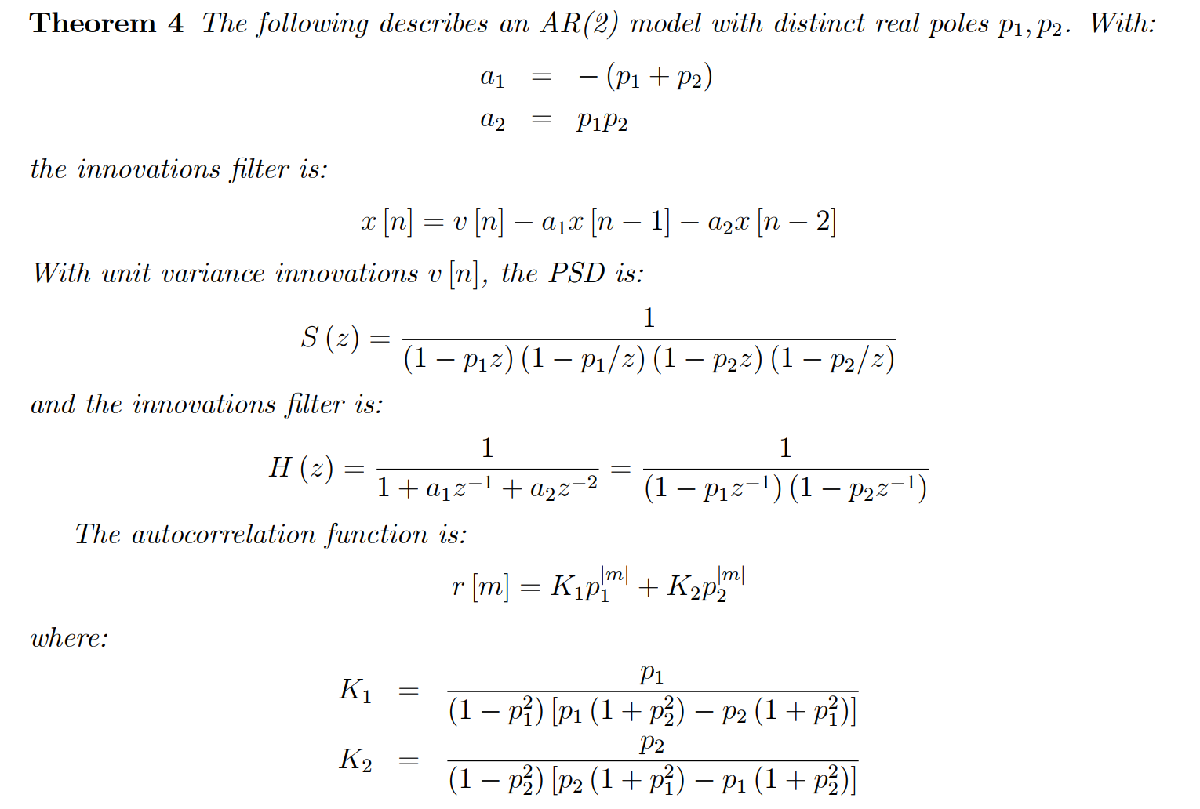

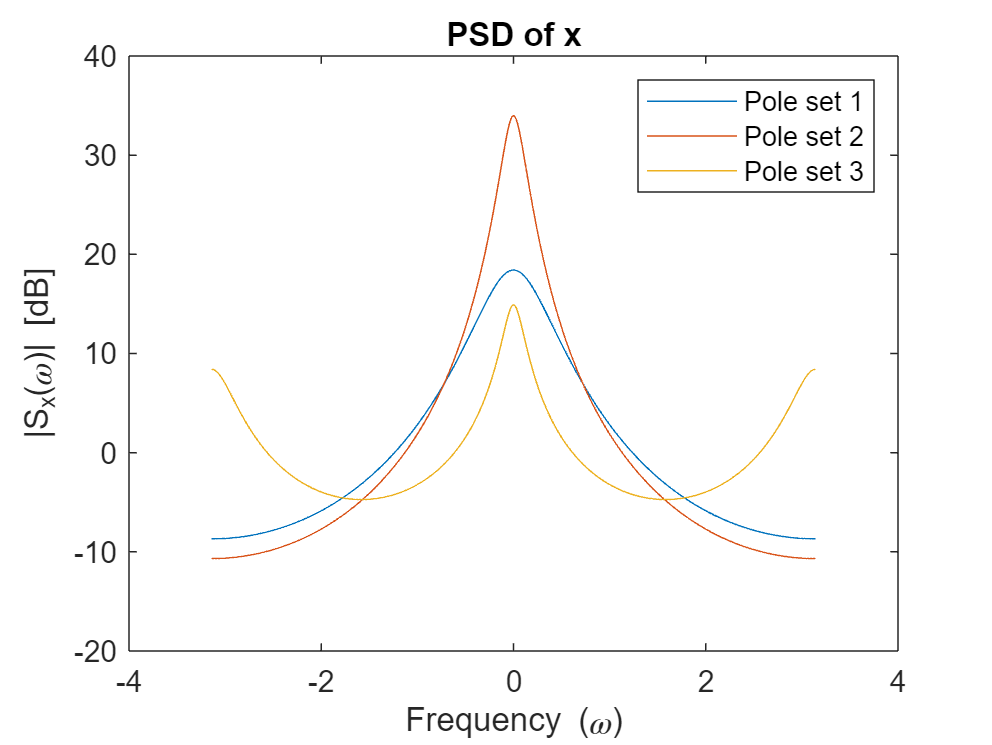

%% Create correlation matrix
% Evaluate PSD for each given pole set:
[R_pole_set1, r_pole_set1, Sx_pole_set1] = autocorrelation(Poles(1:2), L, var_v);
[R_pole_set2, r_pole_set2, Sx_pole_set2] = autocorrelation(Poles(3:4), L, var_v);
[R_pole_set3, r_pole_set3, Sx_pole_set3] = autocorrelation(Poles(5:6), L, var_v);

% Plot the Sx plot:
w = linspace(-pi, pi, 1000);
figure;
plot(w, 10*log10(abs(Sx_pole_set1)));
title("PSD of x");
ylabel("|S_x(\omega)| [dB]");
xlabel("Frequency (\omega)");
hold on;
plot(w, 10*log10(abs(Sx_pole_set2)));
hold on;
plot(w, 10*log10(abs(Sx_pole_set3)));
legend("Pole set 1", "Pole set 2", "Pole set 3");

## Perform Checks on the Data:

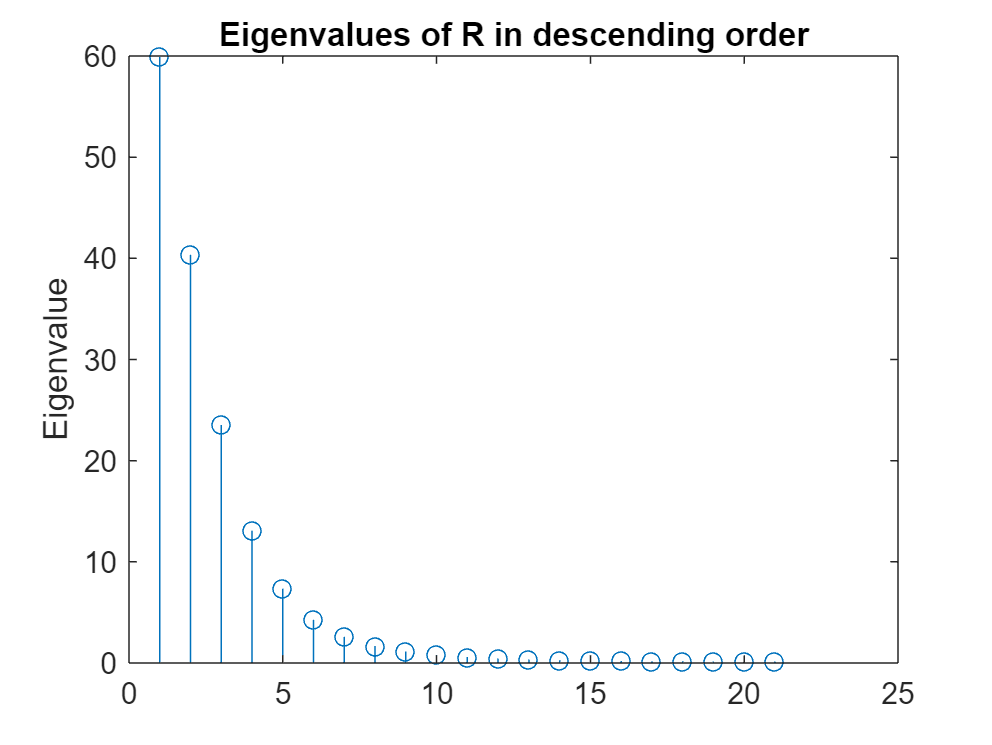

%% Check 1:
check1(R_pole_set1);

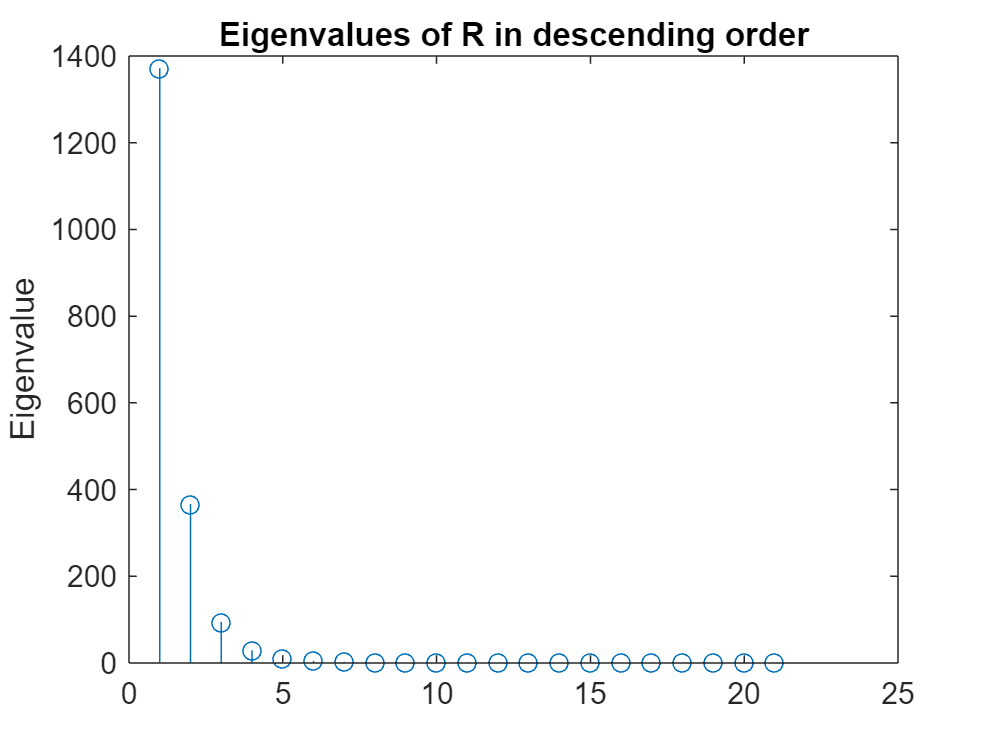

check1(R_pole_set2);

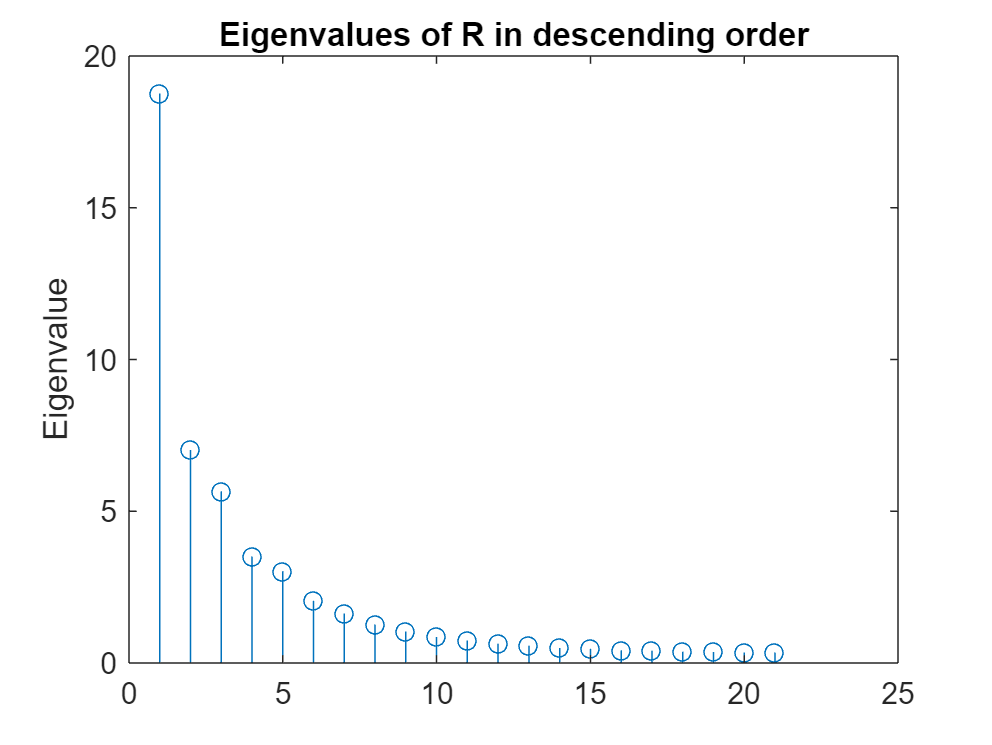

check1(R_pole_set3);


%% Check 2:
[MaxEigenvalues_PoleSet1, MinEigenvalues_PoleSet1] = check2(R_pole_set1, L);
[MaxEigenvalues_PoleSet2, MinEigenvalues_PoleSet2] = check2(R_pole_set2, L);
[MaxEigenvalues_PoleSet3, MinEigenvalues_PoleSet3] = check2(R_pole_set3, L);
Lag = (1:L)';

%% Check 3: Smin <= e-val_min & eval_max <= Smax:
Smin_PoleSet1 = min(Sx_pole_set1) * ones(L, 1);
Smax_PoleSet1 = max(Sx_pole_set1) * ones(L, 1);

Smin_PoleSet2 = min(Sx_pole_set2) * ones(L, 1);
Smax_PoleSet2 = max(Sx_pole_set2) * ones(L, 1);

Smin_PoleSet3 = min(Sx_pole_set3) * ones(L, 1);
Smax_PoleSet3 = max(Sx_pole_set3) * ones(L, 1);

% List Results in table for easy comparison:
eval_table1 = table(MaxEigenvalues_PoleSet1, MinEigenvalues_PoleSet1, Lag, Smax_PoleSet1, Smin_PoleSet1);
disp(eval_table1);

    MaxEigenvalues_PoleSet1    MinEigenvalues_PoleSet1    Lag    Smax_PoleSet1    Smin_PoleSet1
    _______________________    _______________________    ___    _____________    _____________

            14.368                     0.63387             1        69.437           0.13516   
            20.521                     0.25741             2        69.437           0.13516   
             25.94                     0.19104             3        69.437           0.13516   
             30.67                     0.16746             4        69.437           0.13516   
            34.782                     0.15634             5        69.437           0.13516   
            38.351                     0.15016             6        69.437           0.13516   
            41.453                     0.14636             7 


eval_table2 = table(MaxEigenvalues_PoleSet2, MinEigenvalues_PoleSet2, Lag, Smax_PoleSet2, Smin_PoleSet2);
disp(eval_table2);

    MaxEigenvalues_PoleSet2    MinEigenvalues_PoleSet2    Lag    Smax_PoleSet2    Smin_PoleSet2
    _______________________    _______________________    ___    _____________    _____________

            178.57                      1.0443             1        2497.3          0.085496   
            265.66                     0.19655             2        2497.3          0.085496   
            350.56                     0.13005             3        2497.3          0.085496   
            432.94                     0.10982             4        2497.3          0.085496   
            512.55                     0.10097             5        2497.3          0.085496   
            589.24                    0.096251             6        2497.3          0.085496   
            662.95                    0.093424             7 


eval_table3 = table(MaxEigenvalues_PoleSet3, MinEigenvalues_PoleSet3, Lag, Smax_PoleSet3, Smin_PoleSet3);
disp(eval_table3);

    MaxEigenvalues_PoleSet3    MinEigenvalues_PoleSet3    Lag    Smax_PoleSet3    Smin_PoleSet3
    _______________________    _______________________    ___    _____________    _____________

              3.23                        1.53             1        30.837           0.33685   
            4.7805                      0.5814             2        30.837           0.33685   
            5.8496                     0.55217             3        30.837           0.33685   
            7.1126                     0.43167             4        30.837           0.33685   
            8.1461                     0.42473             5        30.837           0.33685   
            9.2226                     0.38801             6        30.837           0.33685   
            10.166                      0.3851             7 

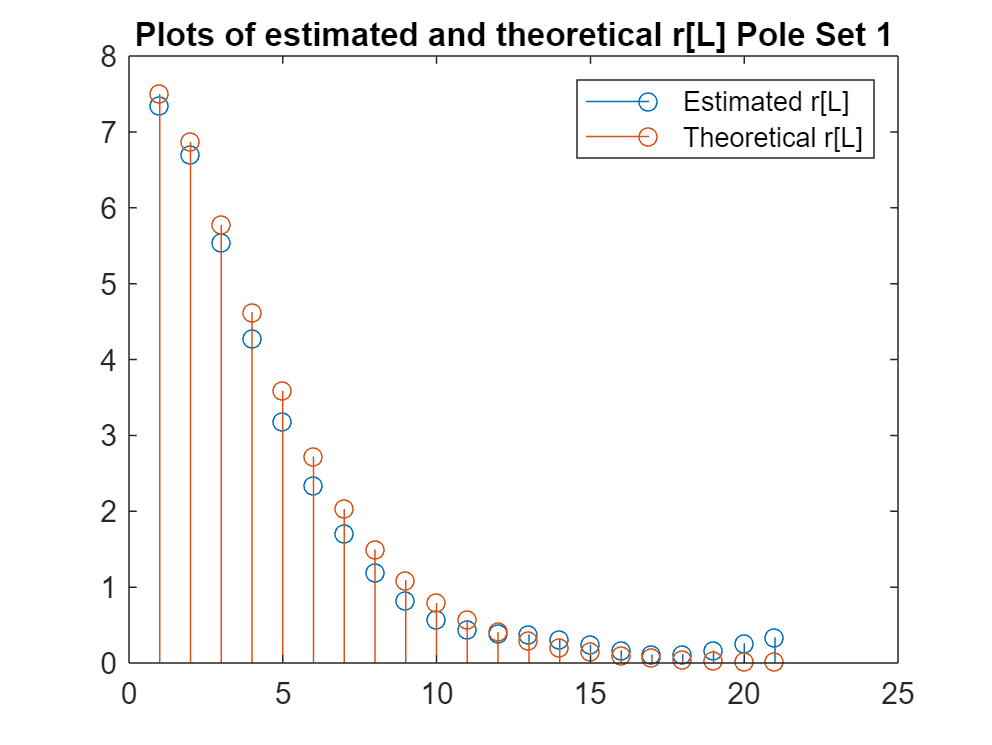


%% Check 4: Estimate r from the data generated in part 1:
[R_est_PoleSet1, r_est_PoleSet1] = estimate_r(X_PS1, N0, L);
[R_est_PoleSet2, r_est_PoleSet2] = estimate_r(X_PS2, N0, L);
[R_est_PoleSet3, r_est_PoleSet3] = estimate_r(X_PS3, N0, L);

% Superimpose plots of estimated r and theoretical calculation of r:
figure;
stem(r_est_PoleSet1);
title("Plots of estimated and theoretical r[L] Pole Set 1");
hold on;
stem(r_pole_set1);
legend("Estimated r[L]", "Theoretical r[L]");

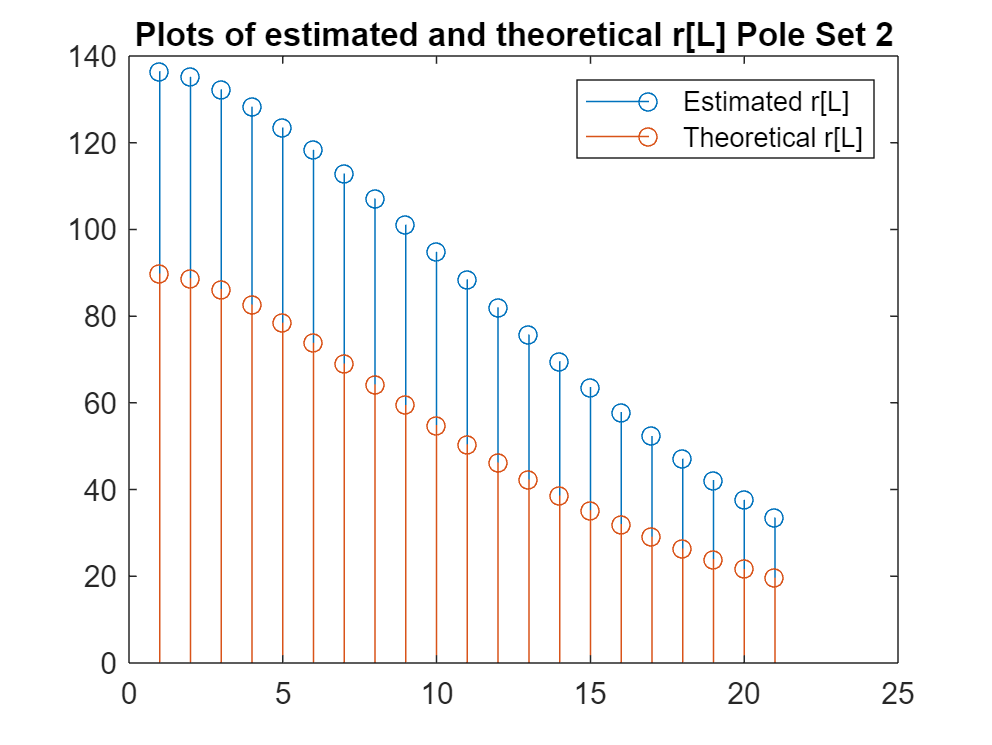


figure;
stem(r_est_PoleSet2);
title("Plots of estimated and theoretical r[L] Pole Set 2");
hold on;
stem(r_pole_set2);
legend("Estimated r[L]", "Theoretical r[L]");

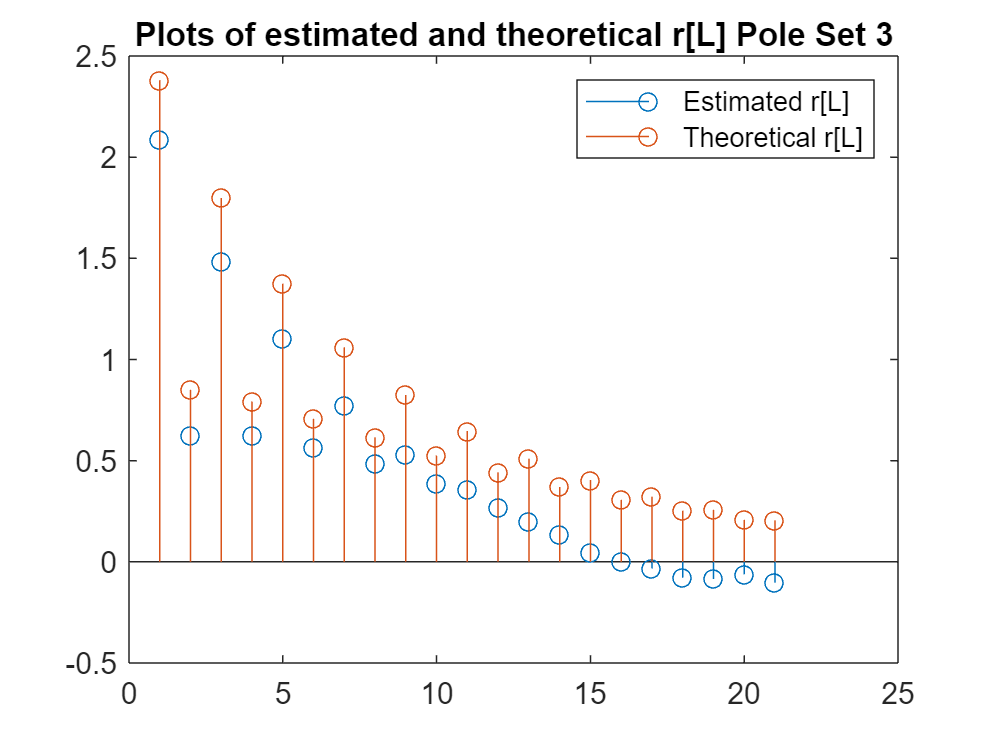


figure;
stem(r_est_PoleSet3);
title("Plots of estimated and theoretical r[L] Pole Set 3");
hold on;
stem(r_pole_set3);
legend("Estimated r[L]", "Theoretical r[L]");


%% Check 5: Compute singular values of X_L:
sing_vals_X_PS1 = 1/N_iter * svd(X_PS1).^2;
sing_vals_X_PS2 = 1/N_iter * svd(X_PS2).^2;
sing_vals_X_PS3 = 1/N_iter * svd(X_PS3).^2;
% NOTE: Singular values 1/N_iter * sing_vals(X).^2 are exactly related to
% the eigenvalues:
evals_R_est_PS1 = flipud(eig(R_est_PoleSet1));
evals_R_est_PS2 = flipud(eig(R_est_PoleSet2));
evals_R_est_PS3 = flipud(eig(R_est_PoleSet3));

sing_vs_eval_table = table(sing_vals_X_PS1, evals_R_est_PS1, sing_vals_X_PS2, evals_R_est_PS2, sing_vals_X_PS3, evals_R_est_PS3);
disp(sing_vs_eval_table);

    sing_vals_X_PS1    evals_R_est_PS1    sing_vals_X_PS2    evals_R_est_PS2    sing_vals_X_PS3    evals_R_est_PS3
    _______________    _______________    _______________    _______________    _______________    _______________

         58.369             58.369             2158.8             2158.8             13.833             13.833    
         39.242             39.242             480.63             480.63             7.3719             7.3719    
         24.515             24.515             87.173             87.173             4.4362             4.4362    
          14.32              14.32             25.053             25.053             3.4612             3.4612    
         8.1186             8.1186             11.516             11.516             2.5676             2



%% Check 6: Compute r[0] from estimate and compare with theoretical
r0_est_PoleSet1 = (1/(2*pi)) * sum(Sx_pole_set1(:)*(w(2)-w(1)));
r0_theoretical_PoleSet1 = r_pole_set1(1);

r0_est_PoleSet2 = (1/(2*pi)) * sum(Sx_pole_set2(:)*(w(2)-w(1)));
r0_theoretical_PoleSet2 = r_pole_set2(1);

r0_est_PoleSet3 = (1/(2*pi)) * sum(Sx_pole_set3(:)*(w(2)-w(1)));
r0_theoretical_PoleSet3 = r_pole_set3(1);

Pole_Sets = [0.7, 0.6 ; 0.9, 0.8 ; 0.9, -0.8];
r0_est = [r0_est_PoleSet1 ; r0_est_PoleSet2 ; r0_est_PoleSet3];
r0_theoretical = [r0_theoretical_PoleSet1 ; r0_theoretical_PoleSet2 ; r0_theoretical_PoleSet3];

r0_table = table(Pole_Sets, r0_est, r0_theoretical);
disp(r0_table);

     Pole_Sets     r0_est    r0_theoretical
    ___________    ______    ______________

    0.7     0.6     7.501        7.5008    
    0.9     0.8    89.808        89.808    
    0.9    -0.8    2.3869          2.38    



# Part II - Running LMS Algorithm

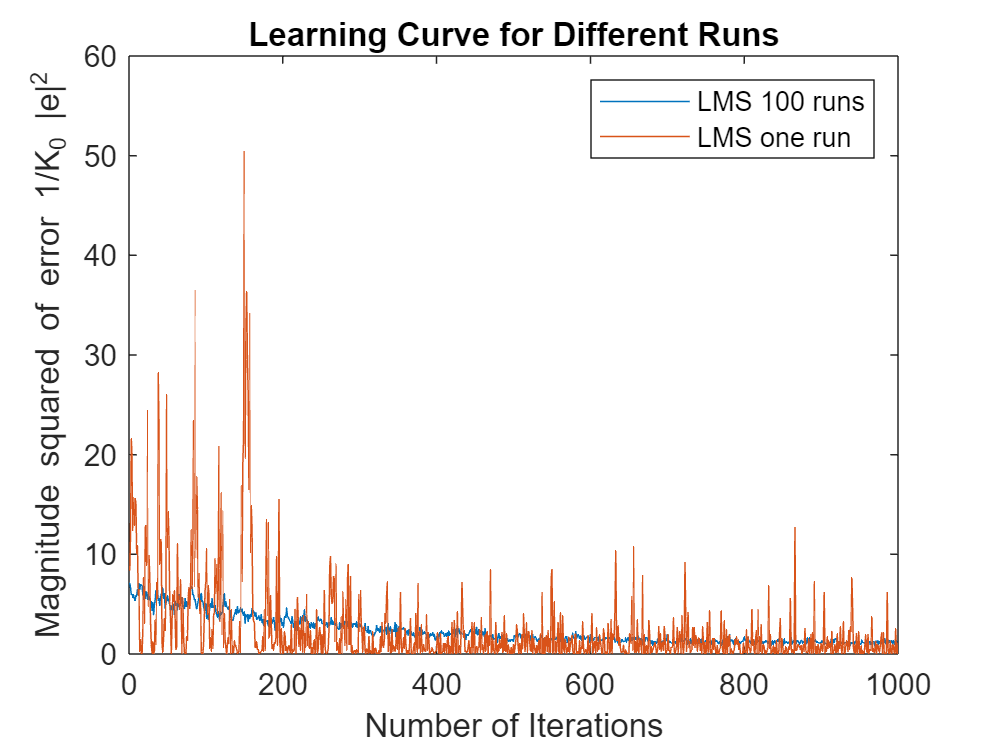

%% Part 3 - LMS Algorithm
% Start with running LMS for M = 2 and pole set 1, for 1000 iterations:
iterations = 1000;
Data_M2_PoleSet1 = generateData(iterations, M(1), Poles(1:2));
K0 = 100;               % Number of runs of LMS for learning curve
% Let J_min = variance of whitening signal v:
J_min = var_v;

% Tweak step size accordingly:
mu = 0.01 * 1 / (Smax_PoleSet1(1));
mu2 = 0.1 * 1 / (Smax_PoleSet1(1));
% Employ LMS Algorithm FOR ONE RUN
[J_LMS_M2_OneRun, D_LMS_M2_OneRun, ~] = LMS(iterations, 1, mu, Poles(1:2), M(1)); 

%% LMS Algorithm Runs:
% Run LMS for 100 runs with Pole Set 1: M = 2, 4, 10:
[J_LMS_M2_PS1, D_LMS_M2_PS1, W_final_M2_PS1] = LMS(iterations, K0, mu, Poles(1:2), M(1));

[J_LMS_M4_PS1, D_LMS_M4_PS1, W_final_M4_PS1] = LMS(iterations, K0, mu, Poles(1:2), M(2));
[J_LMS_M10_PS1, D_LMS_M10_PS1, W_final_M10_PS1] = LMS(iterations, K0, mu, Poles(1:2), M(3));

% Run LMS for 100 runs with Pole Set 2: M = 2, 4, 10:
[J_LMS_M2_PS2, D_LMS_M2_PS2, W_final_M2_PS2] = LMS(iterations, K0, mu, Poles(3:4), M(1));

[J_LMS_M4_PS2, D_LMS_M4_PS2, W_final_M4_PS2] = LMS(iterations, K0, mu, Poles(3:4), M(2));
[J_LMS_M10_PS2, D_LMS_M10_PS2, W_final_M10_PS2] = LMS(iterations, K0, mu, Poles(3:4), M(3));

% Run LMS for 100 runs with Pole Set 3: M = 2, 4, 10:
[J_LMS_M2_PS3, D_LMS_M2_PS3, W_final_M2_PS3] = LMS(iterations, K0, mu, Poles(5:6), M(1));

[J_LMS_M4_PS3, D_LMS_M4_PS3, W_final_M4_PS3] = LMS(iterations, K0, mu2, Poles(5:6), M(1));
[J_LMS_M10_PS3, D_LMS_M10_PS3, W_final_M10_PS3] = LMS(iterations, K0, mu2, Poles(5:6), M(1));


% Pack the runs for Pole Set 0.7, 0.6:
J_LMS_PS1 = [J_LMS_M2_PS1 ; J_LMS_M4_PS1 ; J_LMS_M10_PS1];
D_LMS_PS1 = [D_LMS_M2_PS1 ; D_LMS_M4_PS1 ; D_LMS_M10_PS1];

% Pack the runs for Pole Set 0.9, 0.8:
J_LMS_PS2 = [J_LMS_M2_PS2 ; J_LMS_M4_PS2 ; J_LMS_M10_PS2];
D_LMS_PS2 = [D_LMS_M2_PS2 ; D_LMS_M4_PS2 ; D_LMS_M10_PS2];

% Pack the runs for Pole Set 0.9, -0.8:
J_LMS_PS3 = [J_LMS_M2_PS3 ; J_LMS_M4_PS3 ; J_LMS_M10_PS3];
D_LMS_PS3 = [D_LMS_M2_PS3 ; D_LMS_M4_PS3 ; D_LMS_M10_PS3];


% Plot the learning curve superimposed with one run:
figure;
plot(1:iterations, J_LMS_M2_PS1);
title("Learning Curve for Different Runs")
xlabel("Number of Iterations");
ylabel("Magnitude squared of error 1/K_0 |e|^2");
hold on;
plot(1:iterations, J_LMS_M2_OneRun);
legend("LMS 100 runs", "LMS one run");

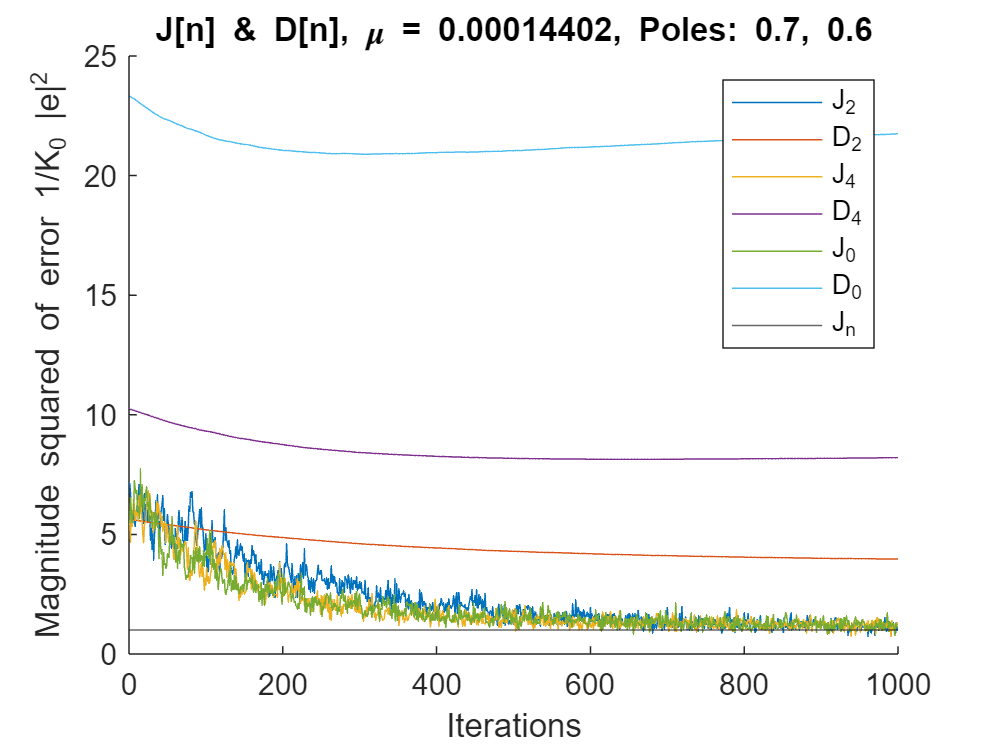


% Plot the learning curve superimposed with mean-square deviation curve:
plotJandD(J_LMS_PS1, D_LMS_PS1, J_min, iterations, Poles(1:2), mu);

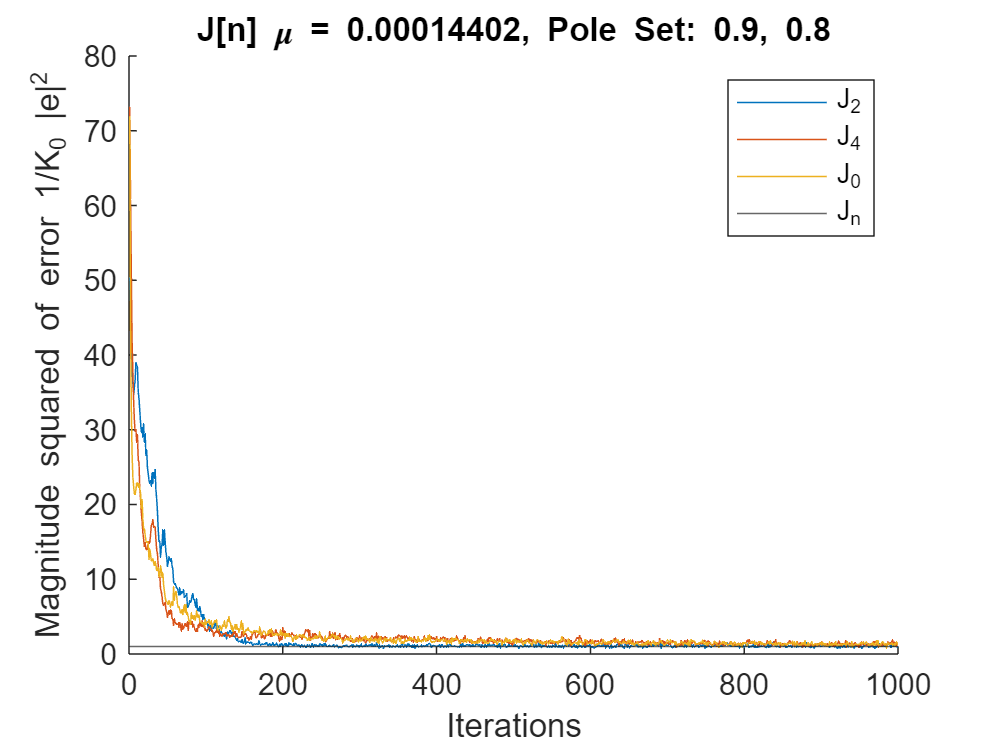


% Make figures for the other J[n] curves for each additional pole set:
plotJ(J_LMS_PS2, J_min, iterations, Poles(3:4), mu);

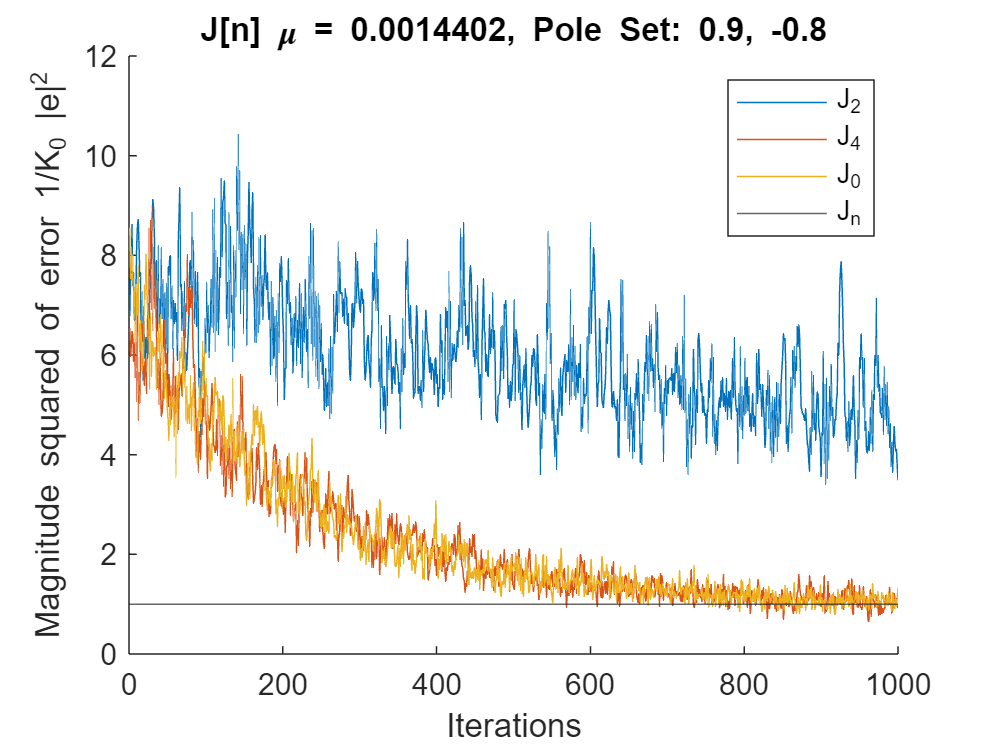

plotJ(J_LMS_PS3, J_min, iterations, Poles(5:6), mu2);


% Compute the misadjustment for the 100 runs of LMS:
Misadjustment_PS1 = zeros(3, 1);
for i = 1:3
    Misadjustment_PS1(i, 1) = misadjustment(J_LMS_PS1(i, :), J_min);
end
Misadjustment_PS2 = zeros(3, 1);
for i = 1:3
    Misadjustment_PS2(i, 1) = misadjustment(J_LMS_PS1(i, :), J_min);
end
Misadjustment_PS3 = zeros(3, 1);
for i = 1:3
    Misadjustment_PS3(i, 1) = misadjustment(J_LMS_PS1(i, :), J_min);
end
Order_M = [2 ; 4 ; 10];
Misadjustment_table = table(Order_M, Misadjustment_PS1, Misadjustment_PS2, Misadjustment_PS3);
disp(Misadjustment_table);

    Order_M    Misadjustment_PS1    Misadjustment_PS2    Misadjustment_PS3
    _______    _________________    _________________    _________________

       2             1.153                1.153                1.153      
       4            1.2178               1.2178               1.2178      
      10            1.2193               1.2193               1.2193      



## Comments

    From my own findings, running each algorithm with different parameters and what not, there are some key things to pay attention to when it comes to running LMS. To start, the slower the rate of convergence, the worse the misadjustment becomes. This makes sense because if the algorithm requires a very small step size, then in the short run, the updated weight vectors won't be close enough to the optimal weight since it is moving so slowly. Thus, the faster the rate of convergence, the lower the misadjustment. However, it is very important to realize that even if we increase the step size for a faster rate of convergence, the algorithm may become unstable which is of course undesireable.

    Furthermore, it seems quite obvious that the order M of the algorithm is directly proportional to increasing step size. In analyses of superimposed plots of different M's using the same step size, it appears as if the learning curve for higher order M converges much faster than lower order M.

    Lastly, consideration of the poles themselves, used in each run of LMS, proved to have an effect on the rate of convergence and stability. In particular, throughout my entire time testing different cases of LMS, aside from the cases shown in this example code (feel free to tweak parameters to test for yourself), it seemed as if the pole set (0.9, 0.8) had the least stability among the others. What is interesting is that the pole set (0.9, -0.8) had much better stability than this least stability case, given the only change was the -0.8 vs +0.8 term.

% Display W_final weights obtained at the end of the different LMS runs:
W_opt_PS1 = [(Poles(1) + Poles(2)), -(Poles(1) * Poles(2))];
W_opt_PS2 = [(Poles(3) + Poles(4)), -(Poles(3) * Poles(4))];
W_opt_PS3 = [(Poles(5) + Poles(6)), -(Poles(5) * Poles(6))];

W_final_PS1 = [W_opt_PS1 ; W_final_M2_PS1' ; W_final_M4_PS1(1:2)' ; W_final_M10_PS1(1:2)'];
W_final_PS2 = [W_opt_PS2 ; W_final_M2_PS2' ; W_final_M4_PS2(1:2)' ; W_final_M10_PS2(1:2)'];
W_final_PS3 = [W_opt_PS3 ; W_final_M2_PS3' ; W_final_M4_PS3(1:2)' ; W_final_M10_PS3(1:2)'];

M_Order = ["W_opt" ; 2 ; 4 ; 10];
W_final_table = table(M_Order, W_final_PS1, W_final_PS2, W_final_PS3);
disp(W_final_table);

    M_Order       W_final_PS1           W_final_PS2            W_final_PS3    
    _______    __________________    __________________    ___________________

    "W_opt"       1.3       -0.42       1.7       -0.72        0.1        0.72
    "2"        1.3696    -0.60724    1.5159    -0.54684    0.88935    -0.59011
    "4"        1.2862    -0.72938    1.4789      -0.679    0.24149     0.55536
    "10"       1.2874    -0.73263      1.44    -0.68689    0.23829     0.55896



## Comments (Continued)

    As you can see from the table of all the final weight vectors obtained at the end of each LMS run, the first two elements are very close to the optimal/actual parameters (when in a region of stability/convergence). Of course, for all these runs the step size was not changed, but given the rest of the results presented, it should be clear what the trend is. To summarize, the better the rate of convergence/the smaller the misadjustment, the more accurately LMS will produce the optimal weights.

# Part III - Running RLS Algorithm

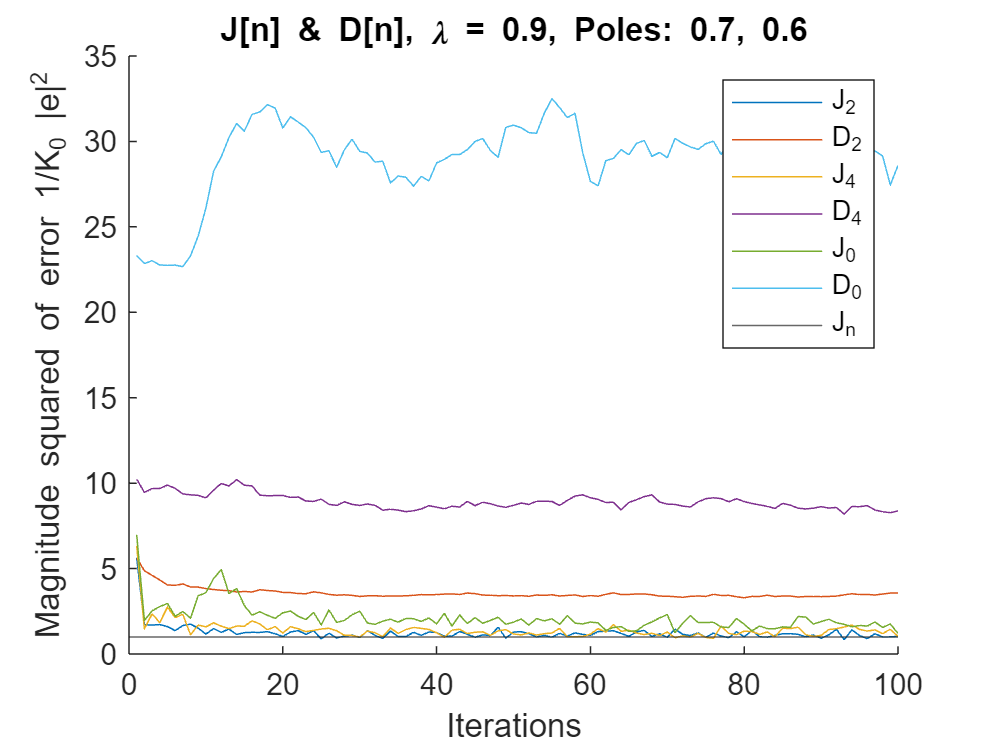

%% Part 4 - RLS Algorithm
% List RLS algorithm parameters:
lamb = 0.9;
del = 1;

% Run RLS for K0 runs (100) with RLS_iterations to start:
RLS_iterations = 100;
% Run RLS for Pole Set 1 and each M
[J_RLS_M2_PS1, D_RLS_M2_PS1, W_final_RLS_M2_PS1] = RLS(RLS_iterations, K0, lamb, del, Poles(1:2), M(1));
[J_RLS_M4_PS1, D_RLS_M4_PS1, W_final_RLS_M4_PS1] = RLS(RLS_iterations, K0, lamb, del, Poles(1:2), M(2));
[J_RLS_M10_PS1, D_RLS_M10_PS1, W_final_RLS_M10_PS1] = RLS(RLS_iterations, K0, lamb, del, Poles(1:2), M(3));

% Run RLS for Pole Set 2 and each M:
[J_RLS_M2_PS2, D_RLS_M2_PS2, W_final_RLS_M2_PS2] = RLS(RLS_iterations, K0, lamb, del, Poles(3:4), M(1));
[J_RLS_M4_PS2, D_RLS_M4_PS2, W_final_RLS_M4_PS2] = RLS(RLS_iterations, K0, lamb, del, Poles(3:4), M(2));
[J_RLS_M10_PS2, D_RLS_M10_PS2, W_final_RLS_M10_PS2] = RLS(RLS_iterations, K0, lamb, del, Poles(3:4), M(3));

% Run RLS for Pole Set 3 and each M:
[J_RLS_M2_PS3, D_RLS_M2_PS3, W_final_RLS_M2_PS3] = RLS(RLS_iterations, K0, lamb, del, Poles(5:6), M(1));
[J_RLS_M4_PS3, D_RLS_M4_PS3, W_final_RLS_M4_PS3] = RLS(RLS_iterations, K0, lamb, del, Poles(5:6), M(2));
[J_RLS_M10_PS3, D_RLS_M10_PS3, W_final_RLS_M10_PS3] = RLS(RLS_iterations, K0, lamb, del, Poles(5:6), M(3));

% Create superimposed plot of the learning curve for each pole set with
% varying M:
J_RLS_PS1 = [J_RLS_M2_PS1 ; J_RLS_M4_PS1 ; J_RLS_M10_PS1];
J_RLS_PS2 = [J_RLS_M2_PS2 ; J_RLS_M4_PS2 ; J_RLS_M10_PS2];
J_RLS_PS3 = [J_RLS_M2_PS3 ; J_RLS_M4_PS3 ; J_RLS_M10_PS3];

D_RLS_PS1 = [D_RLS_M2_PS1 ; D_RLS_M4_PS1 ; D_RLS_M10_PS1];
D_RLS_PS2 = [D_RLS_M2_PS2 ; D_RLS_M4_PS2 ; D_RLS_M10_PS2];
D_RLS_PS3 = [D_RLS_M2_PS3 ; D_RLS_M4_PS3 ; D_RLS_M10_PS3];

% Plot learning curve and mean-square deviation for pole set 1:
plotJandD(J_RLS_PS1, D_RLS_PS1, J_min, RLS_iterations, Poles(1:2), lamb);
title("J[n] & D[n], \lambda = " + lamb + ", Poles: " + Poles(1) + ", " + Poles(2));

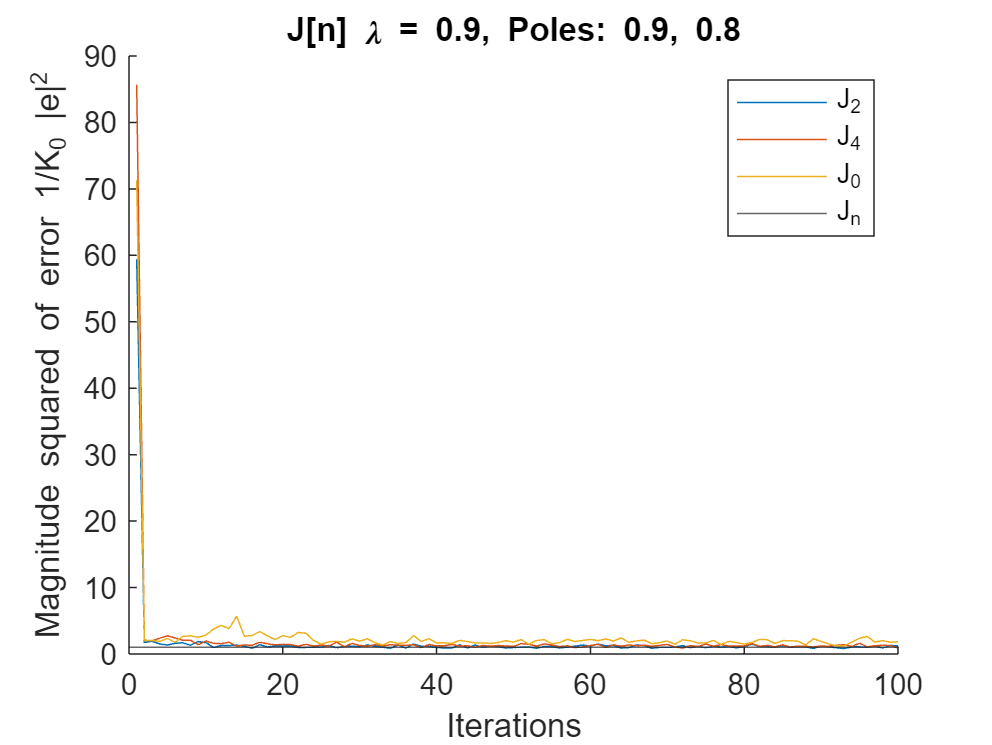


plotJ(J_RLS_PS2, J_min, RLS_iterations, Poles(3:4), lamb);
title("J[n] \lambda = " + lamb + ", Poles: " + Poles(3) + ", " + Poles(4));

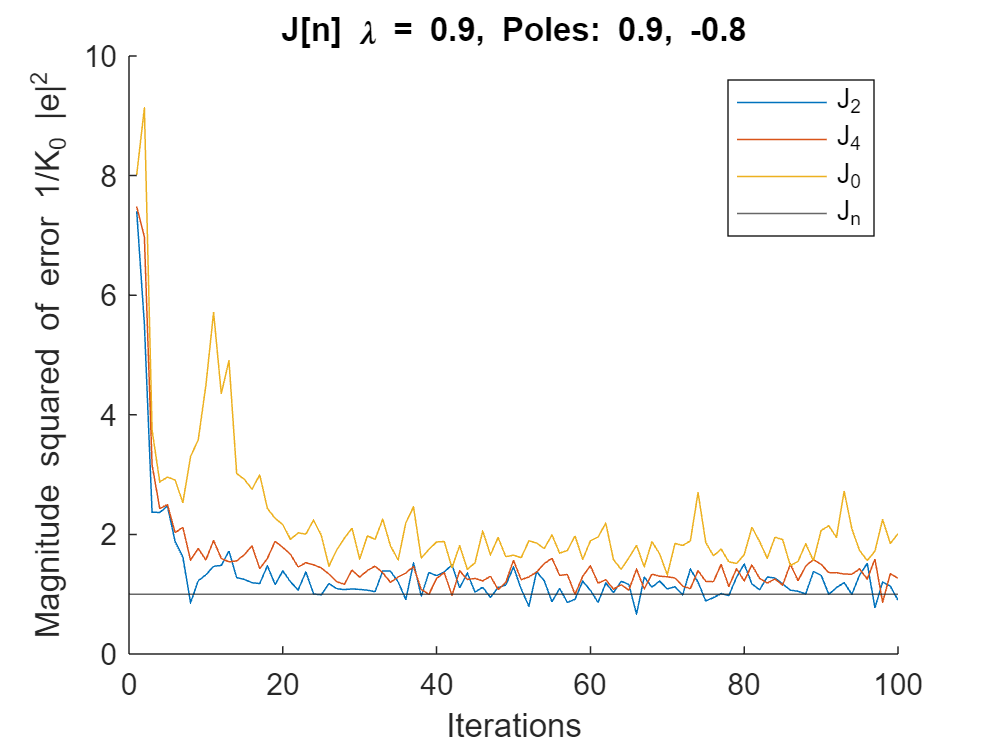


plotJ(J_RLS_PS3, J_min, RLS_iterations, Poles(5:6), lamb);
title("J[n] \lambda = " + lamb + ", Poles: " + Poles(5) + ", " + Poles(6));


% Compute the misadjustment for the 100 runs of RLS:
Misadjustment_RLS_PS1 = zeros(3, 1);
for i = 1:3
    Misadjustment_RLS_PS1(i, 1) = misadjustment(J_RLS_PS1(i, :), J_min);
end
Misadjustment_RLS_PS2 = zeros(3, 1);
for i = 1:3
    Misadjustment_RLS_PS2(i, 1) = misadjustment(J_RLS_PS2(i, :), J_min);
end
Misadjustment_RLS_PS3 = zeros(3, 1);
for i = 1:3
    Misadjustment_RLS_PS3(i, 1) = misadjustment(J_RLS_PS3(i, :), J_min);
end

Misadjustment_RLS_table = table(Order_M, Misadjustment_RLS_PS1, Misadjustment_RLS_PS2, Misadjustment_RLS_PS3);
disp(Misadjustment_RLS_table);

    Order_M    Misadjustment_RLS_PS1    Misadjustment_RLS_PS2    Misadjustment_RLS_PS3
    _______    _____________________    _____________________    _____________________

       2              1.1634                   1.1193                   1.1417        
       4              1.2787                   1.2676                   1.3302        
      10              1.7979                   1.9151                   1.8551        




% Display W_final weights obtained at the end of the different LMS runs:

W_final_RLS_PS1 = [W_opt_PS1 ; W_final_RLS_M2_PS1' ; W_final_RLS_M4_PS1(1:2)' ; W_final_RLS_M10_PS1(1:2)'];
W_final_RLS_PS2 = [W_opt_PS2 ; W_final_RLS_M2_PS2' ; W_final_RLS_M4_PS2(1:2)' ; W_final_RLS_M10_PS2(1:2)'];
W_final_RLS_PS3 = [W_opt_PS3 ; W_final_RLS_M2_PS3' ; W_final_RLS_M4_PS3(1:2)' ; W_final_RLS_M10_PS3(1:2)'];

W_final_RLS_table = table(M_Order, W_final_RLS_PS1, W_final_RLS_PS2, W_final_RLS_PS3);
disp(W_final_RLS_table);

    M_Order     W_final_RLS_PS1       W_final_RLS_PS2        W_final_RLS_PS3   
    _______    __________________    __________________    ____________________

    "W_opt"       1.3       -0.42       1.7       -0.72         0.1        0.72
    "2"        1.2561    -0.40525    1.6221    -0.66099    0.089192     0.60952
    "4"         1.234    -0.43321    1.6666    -0.77417    0.045701     0.66371
    "10"       1.2507    -0.41171    1.6044    -0.68468    0.081134     0.69316



## Comments

    Results are generally the same (interpretation-wise) as in the runs of LMS

- RLS converges much faster than LMS, as is clear in the graphs. On inspection it appears RLS will converge in roughly 20 iterations while it takes LMS (with optimal hyper parameters) roughly 150-200 iterations.

- Misadjustment is quite close to unity which is once again ideal.

- Final weight vector converges quite close, and perhaps even better than LMS across all cases with different pole sets and order M.

# Conclusion

    It is clear that RLS does work much better than LMS, when applicable. Depending on the situation, it could be helpful to employ an adaptive algorithm to update the step size of LMS at certain points to improve performance. The results shown here indicate the various different "features" of LMS and RLS.

# Functions Created

%% Functions Created
% Create function to generate the appropriate data samples based on N_iter,
% order M of the algorithm, and poles of the AR(2) process.

function data_matrix = generateData(num_iterations, M, P)
    % Begin by listing the number of "extra" initial points in v to
    % generate for asymptotic stability such that transient decay is 0.01
    N_init = round(log10(0.01) / log10(0.7));
    N0 = num_iterations + M;

    % Create H(z) ratio of polynomials for innovations filter:
    num = 1;
    den = [1, -(P(1) + P(2)), (P(1) * P(2))];

    % Generate length of prescribed innovations signal, and list variance:
    N = N0 + N_init;
    var_v = 1;
    
    % Generate the innovations signal v with length N:
    v = sqrt(1/var_v) * randn(N, 1)';

    % Obtain data vector x via filtering with innovations signal:
    x = filter(num, den, v);

    % Remove N_init samples from x:
    x(1:N_init) = [];

    % Create the data matrix X (toeplitz):
    col = flipud(x(1 : M + 1)');
    row = x(M + 1 : N0);
    data_matrix = toeplitz(col, row);
end
            
% Create function to compute LMS algorithm specifying K runs, Pole set P,
% order M algorithm, and data vector. Furthermore, function should return
% the learning curve as well for the K runs. LASTLY, return the final W 
% at the final iteration and average across the K runs to see how close 
% it is to the "actual":
function [J, D, W_final] = LMS(iterations, K, step_size, Poles, M)
    % List starting w0 vector to choose depending on size M
    W0 = zeros(1, M);
    W0(1:2) = [1 -1];
    % List the optimal weight vector that we know based on the poles for
    % AR(2): i.e. [-a1, -a2, 0_[(M-2)x1] ]
    W_opt = [(Poles(1) + Poles(2)), -(Poles(1) * Poles(2)), zeros(1, M - 2)];

    % Initialize the mean square error vector for learning curve
    % calculation:
    MSE = zeros(1, iterations);
    % Initialize mean square deviation vector for calculation of D:
    MSD = zeros(1, iterations);

    % Initialize "last element vector" for W:
    W_final = zeros(M, 1);
    for i = 1:K 
        % Initialize W vector for each run of LMS:
        W = zeros(M, iterations);
        % Place W0 at the first index:
        W(:,1) = W0;
        % Initialize error vector at the start of each run:
        error = zeros(1, iterations);
        % Initialize tap-weight deviation vector:
        deviation = zeros(1, iterations);

        % Generate new data for each run:
        % **NOTE: Poles is expecting [1x2] size with the poles:
        data = generateData(iterations, M, Poles(1:2));

        % Employ LMS for each run, "j" iterations:
        for j = 1:iterations
            error(j) = (data(1, j) - data(2 : (M + 1), j)' * W(:, j));
            W_next = W(:, j) + step_size * data(2 : (M + 1), j) * error(j);
            W(:, j + 1) = W_next;
            % Record the deviation in tap weights for each iteration:
            deviation(j) = norm(W(:, j) - W_opt);
        end
        % Update the mean square error vector for the i'th run. Note that
        % the combined error at EACH iteration is desired when we finish
        % all runs:
        MSE = MSE + abs(error).^2;
        % Update mean square deviation vector:
        MSD = MSD + deviation.^2;
        % Also, obtain the final element in the weight vector so we can
        % see the average at the end:
        W_final = W_final + W(:, end);
    end

    % Finally, compute the learning curve for the entire K runs:
    J = MSE / K;
    % Compute the final mean square deviation for the entire k runs:
    D = MSD / K;
    % Average out the final weight vector for the entire K runs:
    W_final = W_final / K;

end

% Create very simple function to obtain the last 50 samples of the learning
% curve to compute J(inf) and thus the misdjustment:
function J_inf = misadjustment(J, J_min)
    % Average the final 50 samples of J (ideally this value should be zero
    % implying that the final 50 samples are equal and the algorithm is in
    % the most stable steady state i.e. J(inf) = 0
    samples = 50;
    J_inf = 1/samples * sum(J((end-samples) : end)) / J_min;
end

% Create function to run the RLS algorithm with forgetting factor lambda,
% order M, Poles P1 P2, and number of iterations. It will return the 
% learning curve, mean square deviation vector, and the final, averaged
% weights across all K runs of the algorithm:
function [J, D, W_final] = RLS(iterations, K, lambda, del, Poles, M)
    % Begin by setting the initial condition P(0):
    P0 = 1/del * eye(M);
    % Initialize P depending on size M:
    P = zeros(M, M*iterations);
    P(:, 1:M) = P0;
    
    % List the optimal weight vector that we know based on the poles for
    % AR(2): i.e. [-a1, -a2, 0_[(M-2)x1] ]
    W_opt = [(Poles(1) + Poles(2)), -(Poles(1) * Poles(2)), zeros(1, (M - 2))];

    % Initialize a guess for weight vector to start the algorithm:
    W0 = zeros(1, M);
    W0(1:2) = [1 -1];
    
    % Initialize the mean square error vector for learning curve
    % calculation:
    MSE = zeros(1, iterations);
    % Initialize mean square deviation vector for calculation of D:
    MSD = zeros(1, iterations);

    % Initialize "last element vector" for W:
    W_final = zeros(M, 1);

    for i = 1:K
        % Generate data matrix for each run of the algorithm
        % ** NOTE: function expects 2 poles:
        data = generateData(iterations, M, Poles(1:2));
        % Initialize each vector used in the algorithm:
        s = zeros(M, iterations);
        k = zeros(M, iterations);
        error = zeros(1, iterations);
        W = zeros(M, iterations);
        W(:, 1) = W0;
        % Initialize tap weight deviation vector:
        deviation = zeros(1, iterations);

        for j = 1:iterations
            P_check = zeros(M);
            e_vals = zeros(M);

            % *** P(1) TECHNICALLY is P(0) => "P(2)" in the DATA IN MATLAB is
            % P(1) in the algorithm formula
            
            s(:, j) = P(:, (1 + M * (j-1)) : M*j) * data(2 : (M + 1), j);
            k(:, j) = (1 / (lambda + (data(2 : (M + 1), j)' * s(:, j)))) * s(:, j);
            error(j) = data(1, j) - (W(:, j)' * data(2 : (M + 1), j));
            % Update W:
            W(:, j + 1) = W(:, j) + k(:, j) * error(j);
            % Update matrix P and CHECK FOR P.D.
            P(:, (1 + M*j) : M*(j+1)) = 1/lambda * P(:, (1 + M * (j-1)) : M*j) - (1/lambda * k(:, j) * s(:, j)');
            % Perform check on P_check at the j'th iteration:
            P_check = P(:, (1 + M*j) : M*(j+1));
            e_vals = eig(P_check);

            % for h = 1:length(e_vals)
                if e_vals(:) <= 0
                    disp("Matrix P not P.D. during run: " + i + ", Iteration: " + j);
                end
            % end

            % Record the deviation in tap weights for each iteration:
            deviation(j) = norm(W(:, j) - W_opt);
            % RLS loops back for the next iteration...
        end
        % Update MSE after each run of the algorithm:
        MSE = MSE + abs(error).^2;
        % Update mean-squared deviation after each run:
        MSD = MSD + deviation.^2;
        % Append the final weight vector to W_final after each run:
        W_final = W_final + W(:, end);
        
    end
    % Create the learning curve, D vector, and the averaged final weights
    % after each run of RLS:
    J = MSE / K;
    D = MSD / K;
    W_final = W_final / K;
       
end


% Create function to compute autocorrelation for AR(2) and 2 real poles:
function [R, r, Sx] = autocorrelation(Poles, M, var_v)
    % Create K terms:
    K1 = Poles(1) / ((1 - Poles(1)^2) * (Poles(1) * (1 + Poles(2)^2) - Poles(2) * (1 + Poles(1)^2)));
    K2 = Poles(2) / ((1 - Poles(2)^2) * (Poles(2) * (1 + Poles(1)^2) - Poles(1) * (1 + Poles(2)^2)));

    % Evaluate r based on K1 and K2:
    r = K1 * (Poles(1) .^ abs((0 : M))) + K2 * (Poles(2) .^ abs((0 : M)));
    % Construct correlation matrix based on r:
    R = toeplitz(r);
    % Evaluate the PSD of X via Sx(w) = var(v)^2 * Sv(w):
    w = linspace(-pi, pi, 1000);
    Sv = (abs(1 ./ (1 - (Poles(2) + Poles(1)) * exp(-1j*w) + (Poles(1) * Poles(2)) * exp(-1j*2*w)))) .^2;

    % Assign Sx output:
    Sx = var_v * Sv;
end

%% Create functions to do the checks for each check in part 2:
function check1(R)
    evals = sort(eig(R), "descend");
    if evals(:) < 0
        disp("At least one eigenvalue in R is less than zero");
    end

    % Create a stem plot of the eigenvalues of the R matrix input:
    figure;
    stem(evals);
    title("Eigenvalues of R in descending order");
    ylabel("Eigenvalue");
end

% Check 2:
function [lambda_max, lambda_min] = check2(R, M)
    lambdas = zeros(M, 2);
    for i = 2 : M + 1
        evals = sort(eig(R(1:i, 1:i)), 'descend');
        % Obtain max and min eval
        lambdas(i-1, :) = [evals(1), evals(end)];
    end
    lambda_max = lambdas(:, 1);
    lambda_min = lambdas(:, 2);
end

% Check 4: estimate r from data X:
function [R_est, r_est] = estimate_r(X, N0, M)
    R_est = 1/(N0 - M) * (X * X');
    r_est = R_est(1, :);
end


% Function to plot each learning curve superimposed with its mean-square
% deviation curve:
function plotJandD(J, D, J_min, iterations, Poles, mu)
    figure;
    hold on;
    plot(1:iterations, J(1, :));
    title("J[n] & D[n], \mu = " + mu + ", Poles: " + Poles(1) + ", " + Poles(2));
    xlabel("Iterations");
    ylabel("Magnitude squared of error 1/K_0 |e|^2");
    plot(1:iterations, D(1, :));
    plot(1:iterations, J(2, :));
    plot(1:iterations, D(2, :));
    plot(1:iterations, J(3, :));
    plot(1:iterations, D(3, :));
    yline(J_min);

    legend("J_M_=_2", "D_M_=_2", "J_M_=_4", "D_M_=_4", "J_M_=_1_0", "D_M_=_1_0", "J_m_i_n");
    hold off;
end

function plotJ(J, J_min, iterations, Poles, mu)
    figure;
    hold on;
    plot(1:iterations, J(1, :));
    title("J[n] \mu = " + mu + ", Pole Set: " + Poles(1) + ", " + Poles(2));
    xlabel("Iterations");
    ylabel("Magnitude squared of error 1/K_0 |e|^2");
    
    plot(1:iterations, J(2, :));
    
    plot(1:iterations, J(3, :));
    
    yline(J_min);

    legend("J_M_=_2", "J_M_=_4", "J_M_=_1_0", "J_m_i_n");
    hold off;
end
